# Flexible beam, LQR

## Pre-requisites

Two link manipulator; four link manipulator

## Introduction

We control the torque of the first joint to regulate the position of a (rough discretization of a) flexible beam represented by four links connected by rotationals spring and dampers. 

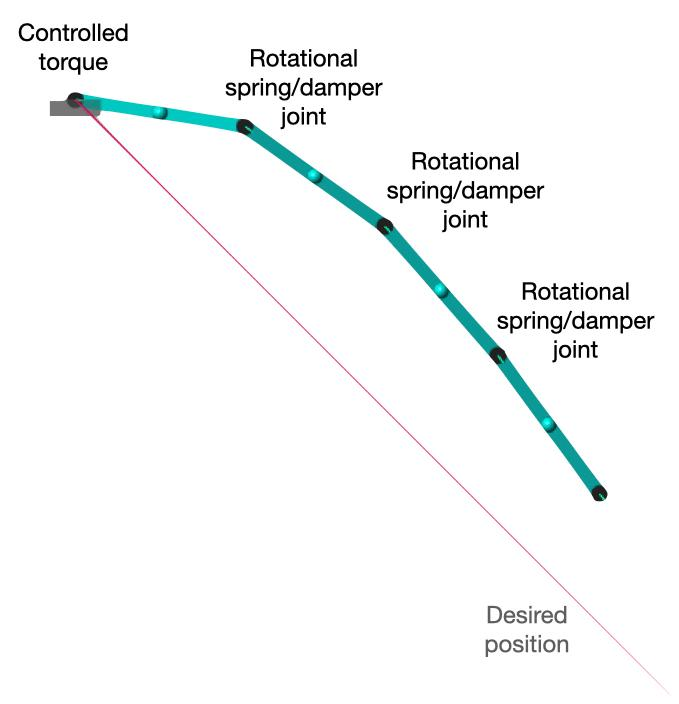 

## Model parameters and references

**Basic robot parameters** - gravity, lenghts, masses - you are welcome to explore different parameters.

Gravity = [0 0 -9.81];

% Robot masses
m1 = 20;     % link1 Mass (kg)
m2 = 20;     % link2 Mass (kg)
m3 = 20;     % link3 Mass (kg)
m4 = 20;      % link4 Mass (kg)

% Link length (this change the robot geometry therefore Matlab will recompile) 
rho1 = 1.5;     % link1 Length (m)
rho2 = 1.5;     % link2 Length (m)
rho3 = 1.5;    % link3 Length (m)
rho4 = 1.5;    % link4 Length (m)

m = [m1 m2 m3 m4];
rho = [rho1 rho2 rho3 rho4];

ee_mass = 20;  %mass attached to the last link (end-effector)

j_k = 20; %rotational spring stiffness
j_kv = 4; %rotational damping coefficient 

init_joint_ang = [pi/2 0 0 0]; %initial configuration

**Initial guess of the desired configuration** (you are welcome to try different configurations). The linearization algorithm below will search for the closest feasible steady-state.

% initial guess of the target state to reach 
%target_state = [-0.494,0,-0.279,0,-0.137,0,-0.049,0];
target_state = [pi/2,0.2,-0*0.279,0,0*-0.137,0,0*-0.049,0];
% initial guess for target torque at steady state 
target_torque = 10;

## Linearisation

To build the LQR controller we linearize the model near the desired position, represented above. 

The linearized state $\tilde{x}$ is given by the vector $[\tilde{q}_1 \ \dot{\tilde{q}}_1 \ \tilde{q}_2 \ \dot{\tilde{q}}_2 \  \tilde{q}_3 \ \dot{\tilde{q}}_3 \ \tilde{q}_4 \ \dot{\tilde{q}}_4]^T$, where $\tilde{q}_i$ is the difference between the $i$th joint angle $q_i$ and the desired one $q_i^*$, and $\dot{\tilde{q}}$ is the difference between the $i$th joint angular velocity $\dot{q}_i$ and the desired one $\dot{q}_i^*$. The controlled torque at the first joint, $u = \tilde{u} + u^*$, is given by the equilibrium torque $u^*$, needed to keep the structure at steady state, plus a correction term that stabilizes the structure near $q^*$.

All linearized data have been computed offline and saved in a "mat" file, that we are now going to load. 

If you like to experiment with a different desired position, you will have to derive a new linearization near that point, using the file linearise.mlx

edit four_link_lin.mlx; %this file illustrates how to linearise the system

save("lin_result.mat");

## LQR controller

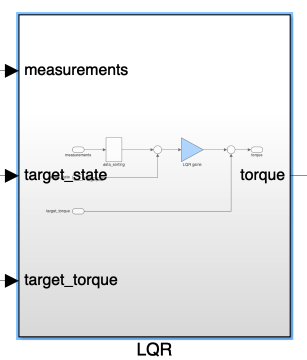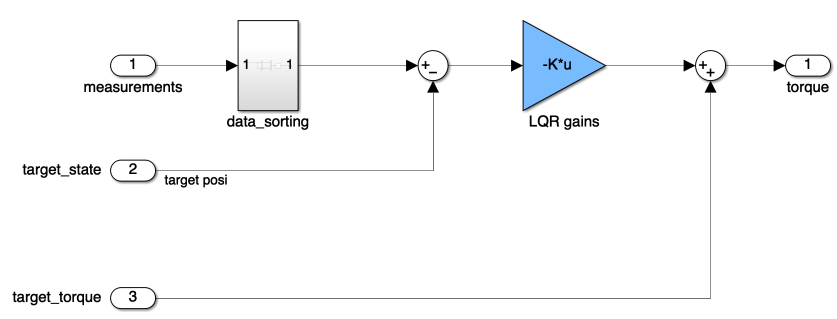

### Design

Extract the relevant model data and check feasibility of the control task.

load("lin_result.mat");

%state matrix
A = lin_plant.A;

%input matrix
B = lin_plant.B; %get single column, related to the first torque


Set the desired target to the best steady-state estimation

%estimated steady-state
target_state = estimated_state

target_state =     1.5467         0    0.0191    0.0000    0.0235   -0.0000    0.0116    0.0000


%estimated torque
target_torque = estimated_torque

target_torque = 9.9998

LQR weights (please explore different Q and R)

% state cost matrix (try different configurations)
Q = diag([1 1 1 1 1 1 1 1])*1000;

% input  cost matrix (try different configurations)
R = 0.1;


LQR gains

% control gains
K = lqr(A,B,Q,R)

K = 1.0e+04 *

    1.3060    0.9228    0.8935    0.6332    0.5138    0.3672    0.2021    0.1470


%check closed loop state feedback poles
eig(A-B*K)

ans = 1.0e+02 *

  -4.5912 + 0.0000i
  -0.4648 + 0.0000i
  -0.0379 + 0.0053i
  -0.0379 - 0.0053i
  -0.0396 + 0.0000i
  -0.0075 + 0.0000i
  -0.0151 + 0.0000i
  -0.0141 + 0.0000i



%actuator saturation - to test with realistic torque constraints
actuator_saturation = 4000; %overall torque saturation

### **Simulation**

model = "four_link_LQR";
open_system(model);

The controller goal is to steer the configuration of the four-link underactuated structure towards the predefined target state, from any initial condition "near" that target state. You are encouraged to test the controller from different initial conditions. You can also extend the simulation horizon beyond 10 seconds if convergence is slow. 

init_joint_ang = [0 0 0 0]; %initial configuration

T = 10;
simulation = sim(model,'StartTime','0','StopTime','T');

Plot response and control action

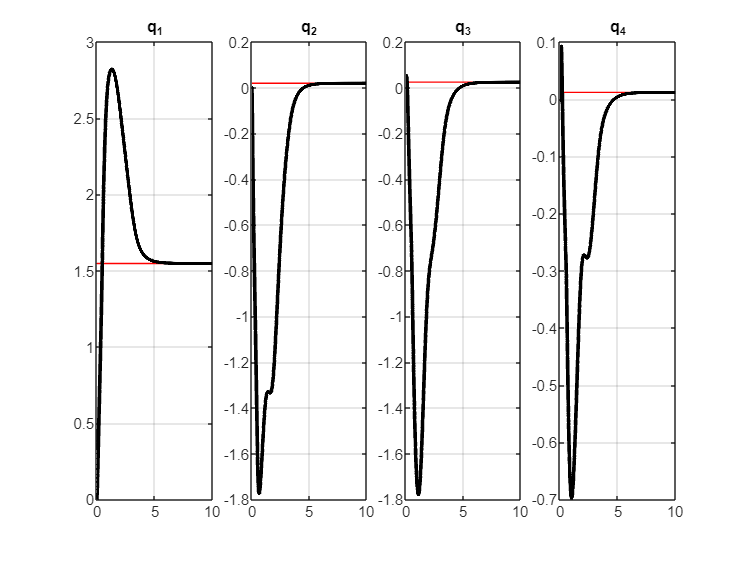

figure
subplot(1,4,1)
plot([0,T],[target_state(1),target_state(1)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,1),'k','linewidth',2);
title('q_1')
grid on;
subplot(1,4,2)
plot([0,T],[target_state(3),target_state(3)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,2),'k','linewidth',2);
title('q_2')
grid on;
subplot(1,4,3)
plot([0,T],[target_state(5),target_state(5)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,3),'k','linewidth',2);
title('q_3')
grid on;
subplot(1,4,4)
plot([0,T],[target_state(7),target_state(7)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,4),'k','linewidth',2);
title('q_4')
grid on;

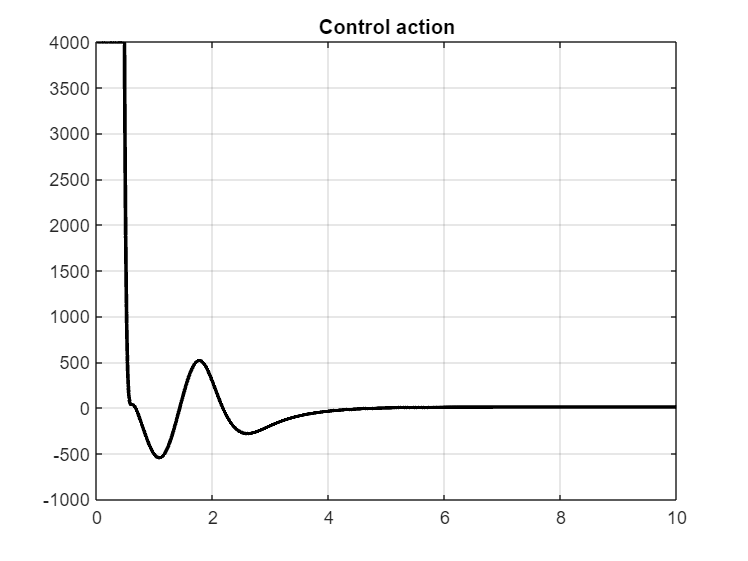


figure
plot(simulation.control_signal.Time,simulation.control_signal.Data,'linewidth',2,'color',[0,0,0]);
title('Control action')
grid on;

## LQR with convergence rate

### Design

The optimality of the LQR controller may enforce a slow decay rate (i.e. long oscillations). To guarantee faster convergence, thus reduce oscillations, we need to enforce a faster decay rate. This can be done by forcing the eigenvalues of the controlled linearized system to be to the left of a certain constant $-\lambda$.

Set the convergence rate by shifting the state matrix

%rate selection
lambda = 1;

A = lin_plant.A + lambda*eye(length(A));


LQR weights

% state cost matrix (try different configurations)
Q = diag([1 1 1 1 1 1 1 1])*10;

% input  cost matrix (try different configurations)
R = 0.5;


LQR gains

% control gains
K = lqr(A,B,Q,R)

K = 1.0e+03 *

    3.3215    1.9079    2.1690    1.3025    1.1982    0.7435    0.4634    0.2934


%check closed loop state feedback poles
eig(A-B*K)

ans = 1.0e+03 *

   -3.8706
   -0.3962
   -0.0216
   -0.0008
   -0.0022
   -0.0027
   -0.0026
   -0.0025



%actuator saturation - to test with realistic torque constraints
actuator_saturation = 4000; %overall torque saturation

### **Simulation**

Run again the simulation with the new controller gain to see the difference from the previous case. You are encouraged to test different initial conditions and also different rates $\lambda$. 

init_joint_ang = [0 0 0 0]; %initial configuration

T = 10;
simulation = sim(model,'StartTime','0','StopTime','T');

Plot response and control action

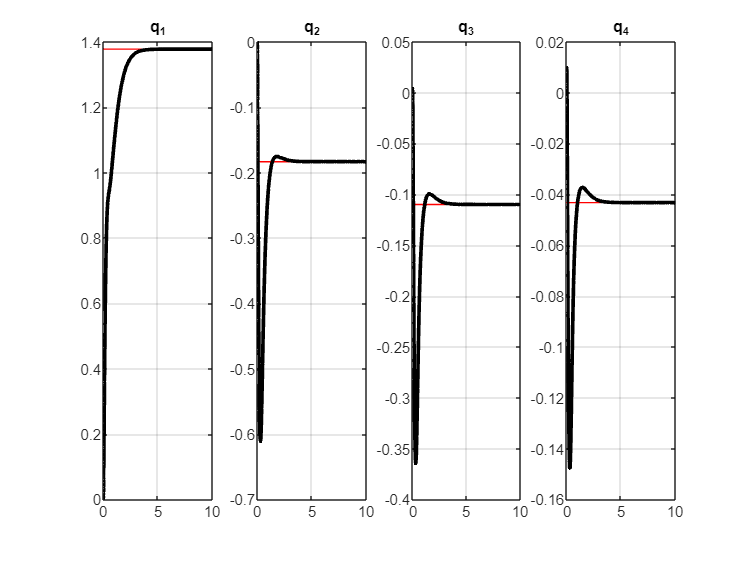

figure
subplot(1,4,1)
plot([0,T],[target_state(1),target_state(1)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,1),'k','linewidth',2);
title('q_1')
grid on;
subplot(1,4,2)
plot([0,T],[target_state(3),target_state(3)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,2),'k','linewidth',2);
title('q_2')
grid on;
subplot(1,4,3)
plot([0,T],[target_state(5),target_state(5)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,3),'k','linewidth',2);
title('q_3')
grid on;
subplot(1,4,4)
plot([0,T],[target_state(7),target_state(7)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,4),'k','linewidth',2);
title('q_4')
grid on;

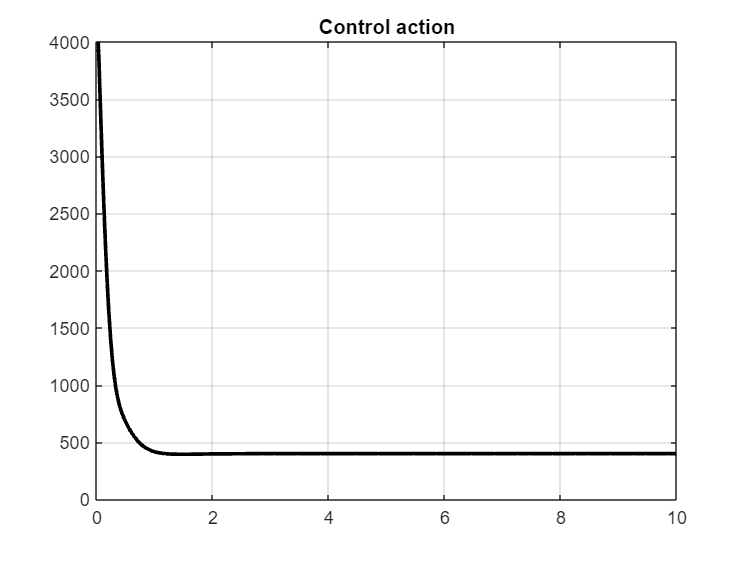


figure
plot(simulation.control_signal.Time,simulation.control_signal.Data,'linewidth',2,'color',[0,0,0]);
title('Control action')
grid on;

Another interesting test is to verify the behavior of the controller for a perturbed target state or for perturbed parameters, that is, when we change the target state or the model without recomputing the controller gains on a new linearization

ee_mass = 12;  %mass attached to the last link (end-effector)

T = 10;
simulation = sim(model,'StartTime','0','StopTime','T');

Plot response and control action

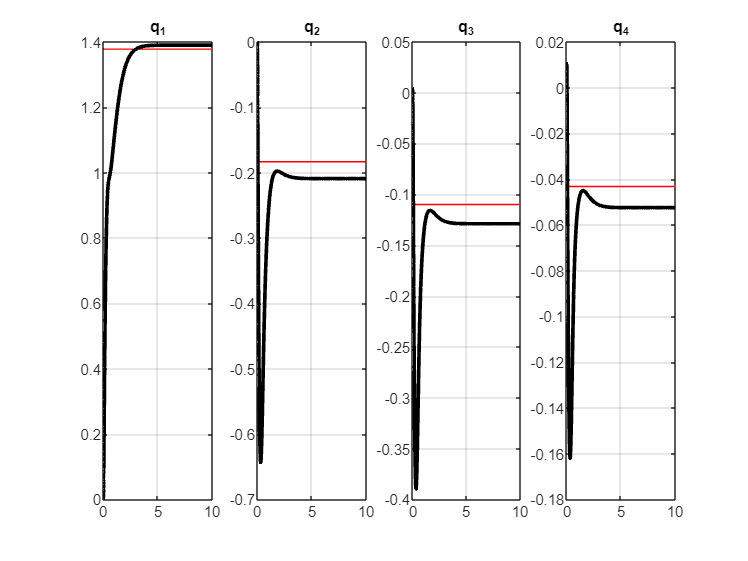

figure
subplot(1,4,1)
plot([0,T],[target_state(1),target_state(1)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,1),'k','linewidth',2);
title('q_1')
grid on;
subplot(1,4,2)
plot([0,T],[target_state(3),target_state(3)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,2),'k','linewidth',2);
title('q_2')
grid on;
subplot(1,4,3)
plot([0,T],[target_state(5),target_state(5)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,3),'k','linewidth',2);
title('q_3')
grid on;
subplot(1,4,4)
plot([0,T],[target_state(7),target_state(7)],'r');
hold on
plot(simulation.joint_signal.Time,simulation.joint_signal.Data(:,4),'k','linewidth',2);
title('q_4')
grid on;

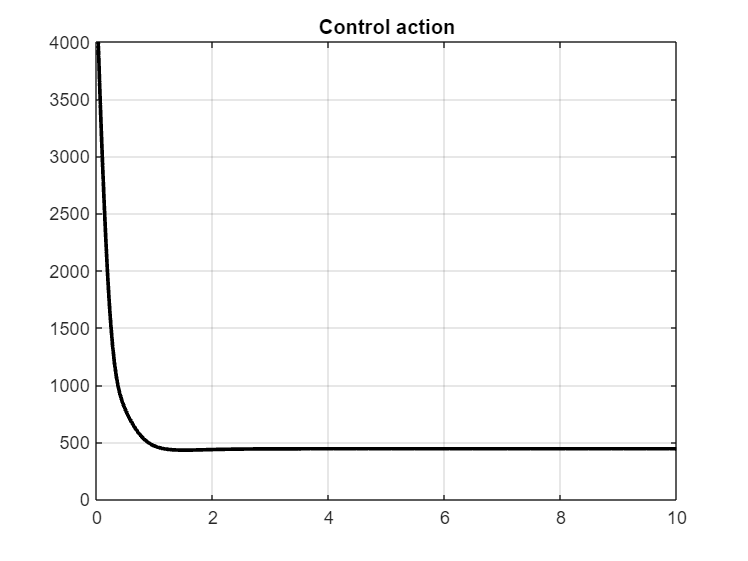


figure
plot(simulation.control_signal.Time,simulation.control_signal.Data,'linewidth',2,'color',[0,0,0]);
title('Control action')
grid on;

In general, the controller will guarantee stability as long as perturbation are small but a steady state error will appear.

save_system(model)
close_system(model)